addpath('C:\Users\prakh\Documents\MATLAB\saved');  
rng(42);

clc; clear; close all;

%% LOAD TRAJECTORY DATA
filename = '09 - 2023-12-08-09-10-46_SRCC_Snow_speed_20250212170056.asc';
trajData = readtable(filename);
latVec_all = trajData.Var2;
lonVec_all = trajData.Var3;
nPointsAll = numel(latVec_all);

fprintf('Trajectory bounding box:\n');

Trajectory bounding box:


fprintf('  lat from %.5f to %.5f\n', min(latVec_all), max(latVec_all));

  lat from 50.52913 to 50.55616


fprintf('  lon from %.5f to %.5f\n', min(lonVec_all), max(lonVec_all));

  lon from 12.77824 to 12.99745



%% DEFINE BASE STATION POSITIONS (lat/lon) & SIMULATION PARAMETERS
% BSpositions_latlon = [
%     50.5300, 12.7500;
%     50.5300, 12.8400;
%     50.5600, 12.7500;
%     50.5600, 12.8400;
%     % 50.5450, 12.7920;
%     50.52751, 12.80250
%     50.5465, 12.8060;
%     % 50.5400, 12.8200;
% ];
BSpositions_latlon = [ ...
            50.54883, 12.7652, 1, 1, 0; ...
            50.56679, 12.99529, 1, 1, 0; ...
             50.56465, 12.95865, 1, 1, 0; ...
             50.53451, 12.83628, 1, 1, 0; ...
             50.55237, 13.0004, 1, 1, 0; ...
             50.53782, 12.95676, 1, 1, 1; ...
             50.53509, 12.99209, 1, 1, 0; ...
             50.54079, 12.91266, 1, 1, 0; ...
             50.57945, 13.00284, 0, 1, 0; ...
             50.547614, 12.859297, 1, 1, 1; ...
             50.53495, 12.872275, 1, 1, 1; ...           
             50.533847, 12.806614, 0, 1, 1; ...
             50.5853778, 13.0023278, 0, 1, 1; ...
             50.577823, 12.9983423, 0, 1, 1; ...
             50.5712973, 12.9973528, 0, 1, 1; ...
             50.5671639, 12.9980112, 0, 1, 1; ...
             50.557275, 12.9990445, 0, 1, 1; ...
             50.5539556, 12.9962667, 0, 1, 1; ...
             50.5485251, 12.9624611, 0, 1, 1; ...
             50.5545528, 12.9521278, 0, 1, 1; ...
             50.5794611, 12.9983556, 0, 0, 1; ...
             50.54629, 12.78962, 0, 1, 1;
             ];
nBS = size(BSpositions_latlon, 1);

scenario = 'uma';
simParams = struct(...
    'txPower',    10, ...       % dBm
    'txGain',     10, ...       % dBi
    'rxGain',     5, ...
    'systemLoss', 0, ...
    'fHz',        700e6, ...    % Hz
    'hBS',        25, ...       % meters
    'hUT',        1.5, ...      % meters
    'h',          1.5, ...      % meters
    'd0',         1, ...
    'BW',         10e6, ...
    'useShadowing',true, ...
    'useFading',    true ...
);
c = physconst('LightSpeed');
simParams.fGHz    = simParams.fHz / 1e9;    % [GHz]
simParams.lambda  = c / simParams.fHz;      % [m]
deltaPL = 0.1;

fGHz = simParams.fHz / 1e9;
PL_100m = 28 + 22*log10(100) + 20*log10(fGHz);   % UMa-LOS, 100 m
fprintf('Expected PL at 100 m (LOS, UMa) ≈ %.1f dB\n', PL_100m);

Expected PL at 100 m (LOS, UMa) ≈ 68.9 dB



simParams.d_bp = (4 * simParams.hBS * simParams.hUT * simParams.fHz) / c;

fprintf('Breakpoint distance d_bp = %.2f m\n', simParams.d_bp);

Breakpoint distance d_bp = 350.24 m



%%%%%%%%%%%SANITY
% ---------- ideal test (no noise) ------------
[rssi_test,~,isLOS_test] = calculateRSSI_3GPP([0 0],[100 0],simParams,'uma');   % 100 m
d_est_test = rssi2distance_3gpp(rssi_test, isLOS_test, simParams);
fprintf('True = 100 m   Inverted = %.6f m\n', d_est_test);

True = 100 m   Inverted = 162.255165 m




%% CONVERT TRAJECTORY AND BS POSITIONS TO LOCAL CARTESIAN (x,y) COORDINATES
% Choose the first BS as the reference
latRef = BSpositions_latlon(1,1);
lonRef = BSpositions_latlon(1,2);

% Convert BS positions (lat/lon to local XY in meters)
xBS = zeros(1, nBS);
yBS = zeros(1, nBS);
for b = 1:nBS
    [xBS(b), yBS(b)] = latLon2localXY(BSpositions_latlon(b,1), BSpositions_latlon(b,2), latRef, lonRef);
end
anchorPos2D = [xBS; yBS];  % 2 x nBS

% Convert trajectory positions to local XY (meters)
[xTraj_all, yTraj_all] = latLon2localXY(latVec_all, lonVec_all, latRef, lonRef);

%% FILTER TRAJECTORY POINTS BY COVERAGE (Using Euclidean Distance in Cartesian Coordinates)
% Compute Euclidean distance from each trajectory point to each BS
distMatrix = zeros(nPointsAll, nBS);
for b = 1:nBS
    distMatrix(:, b) = sqrt((xTraj_all - xBS(b)).^2 + (yTraj_all - yBS(b)).^2);
end
maxRange_m = 5000; % meters
% inCoverageMask = all(distMatrix <= maxRange_m, 2);
numRequired = 4;
inCoverageMask = sum(distMatrix <= maxRange_m, 2) >= numRequired;

xTraj_in = xTraj_all(inCoverageMask);
yTraj_in = yTraj_all(inCoverageMask);
nPointsIn = sum(inCoverageMask);
fprintf('Kept %d points (%.1f%%) within %.1f km of k nearest BS.\n', nPointsIn, 100*nPointsIn/nPointsAll, maxRange_m/1000);

Kept 15689 points (100.0%) within 5.0 km of k nearest BS.



% bearings at anchor A for DOA estimation
xA = xBS(1);
yA = yBS(1);

% Compute bearing to every trajectory point:
trajAngles = atan2d( yTraj_in - yA,  xTraj_in - xA );  
minAngle = floor(min(trajAngles));  
maxAngle = ceil (max(trajAngles));  
fprintf('DOA span: [%d°, %d°]\n', minAngle, maxAngle);

DOA span: [-30°, 4°]



%% RSSI & DISTANCE INVERSION USING CARTESIAN COORDINATES
rssiMatrix_in = zeros(nPointsIn, nBS);
betaMatrix_in  = zeros(nPointsIn,nBS);   % NEW
losMatrix_in   = false(nPointsIn,nBS);   % NEW

for i = 1:nPointsIn
    tgtPos = [xTraj_in(i), yTraj_in(i)]; % Target position in local XY (meters)
    for b = 1:nBS
        anchorPos = anchorPos2D(:, b)';  % BS position (1x2)

        [rssiVal, ~, isLOS, beta] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario);
        
        rssiMatrix_in(i, b) = rssiVal;
        betaMatrix_in(i,b) = beta;
        losMatrix_in(i,b)  = isLOS;
    end
end

windowSize   = 30;
rssi_lin     = 10.^(rssiMatrix_in/10);       % linear scale
rssi_lin_avg = movmean(rssi_lin, [windowSize-1,0], 1);
rssi_avg     = 10*log10(rssi_lin_avg);       % back to dBm

k = 1.38e-23; T = 290;
noisePower_W = k * T * simParams.BW;
noiseFigure_dB = 6;
noiseFloor_dBm = 10 * log10(noisePower_W * 1000) + noiseFigure_dB;
simParams.noiseFloor_dBm = noiseFloor_dBm;

% SNR in dB
snrMatrix_dB = rssiMatrix_in - noiseFloor_dBm;

% linear‐scale SNR:
snrMatrix_lin = 10.^(snrMatrix_dB / 10);

minSNR_dB = min(snrMatrix_dB(:));
maxSNR_dB = max(snrMatrix_dB(:));
fprintf('Per-link SNR range: [%.1f, %.1f] dB\n', minSNR_dB, maxSNR_dB);

Per-link SNR range: [-95.8, 72.0] dB



% RSSI Inversion
[nPointsIn, nBS] = size(rssiMatrix_in);
xBS = anchorPos2D(1,:);    % 1×nBS
yBS = anchorPos2D(2,:);    % 1×nBS
xT  = xTraj_in(:);         % nPointsIn×1
yT  = yTraj_in(:);         % nPointsIn×1

dx = xT(:,ones(1,nBS)) - xBS(ones(nPointsIn,1), :);
dy = yT(:,ones(1,nBS)) - yBS(ones(nPointsIn,1), :);
trueDistMatrix_in = sqrt( dx.^2 + dy.^2 );

estDistMatrix_in = rssi2distance_3gpp(rssiMatrix_in, losMatrix_in, simParams);

fprintf('True range:    [%.1f, %.1f] m\n', min(trueDistMatrix_in(:)), max(trueDistMatrix_in(:)));

True range:    [15.5, 16449.5] m


fprintf('Estimated range: [%.1f, %.1f] m\n', min(estDistMatrix_in(:)), max(estDistMatrix_in(:)));

Estimated range: [0.0, 213682.3] m


err = estDistMatrix_in - trueDistMatrix_in;
MAE_dist   = mean(abs(err(:)));                      
MSE_dist   = mean(err(:).^2);                     
RMSE_dist  = sqrt(MSE_dist);                       

fprintf('Estimated distance: MAE  = %.2f m\n',MAE_dist);

Estimated distance: MAE  = 2953.74 m


fprintf('MSE  = %.2f m^2\n',MSE_dist);

MSE  = 33894720.36 m^2


fprintf('RMSE = %.2f m\n',RMSE_dist);

RMSE = 5821.92 m


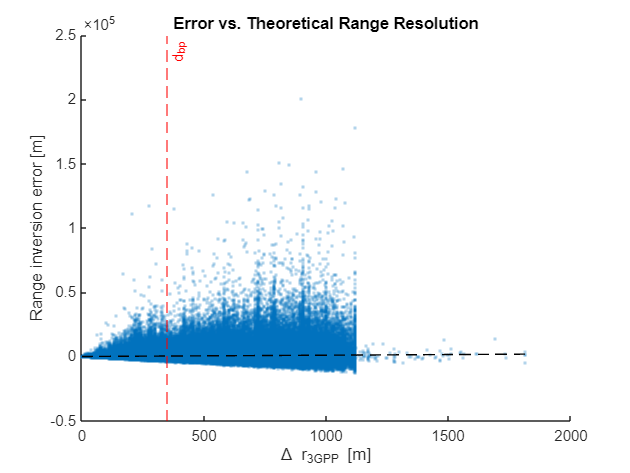


deltaR_3GPP = (10.^(deltaPL ./ betaMatrix_in) - 1) .* trueDistMatrix_in;
% fprintf('Estimated range resolution: RR = %.2f m\n', deltaR_3GPP);

% Flatten into vectors
errs_RR = err(:);
delRR = deltaR_3GPP(:);

% scatter error vs. theoretical resolution
figure; scatter(delRR, errs_RR, '.', 'MarkerEdgeAlpha', .3);
hold on; 
plot([0 max(delRR)], [0  max(delRR)], 'k--');  % 1:1 line
xline(simParams.d_bp, 'r--','d_{bp}');
xlabel('\Delta r_{3GPP} [m]'); ylabel('Range inversion error [m]');
title('Error vs. Theoretical Range Resolution');


%% True Position Matrix
truePosMatrix_in = [xTraj_in'; yTraj_in'];  % 2 x nPointsIn

%% WLS initial guess
k = 4; % using k anchors

[estPosLS_i, rmseLS_in, errWLS] = estimatePositionWLS(anchorPos2D, estDistMatrix_in, snrMatrix_dB, k, truePosMatrix_in');
fprintf('WLS RMSE = %.2f m\n', rmseLS_in);

WLS RMSE = 5229.75 m



% WLS error metrics:
MSE_LS  = mean(errWLS.^2);
RMSE_LS = sqrt(MSE_LS);
MAE_LS  = mean(errWLS);
fprintf('=== Overall Initial Guess: MSE = %.2f m^2, RMSE = %.2f m, MAE = %.2f m ===\n', MSE_LS, RMSE_LS, MAE_LS);

=== Overall Initial Guess: MSE = 27350333.30 m^2, RMSE = 5229.75 m, MAE = 1653.72 m ===


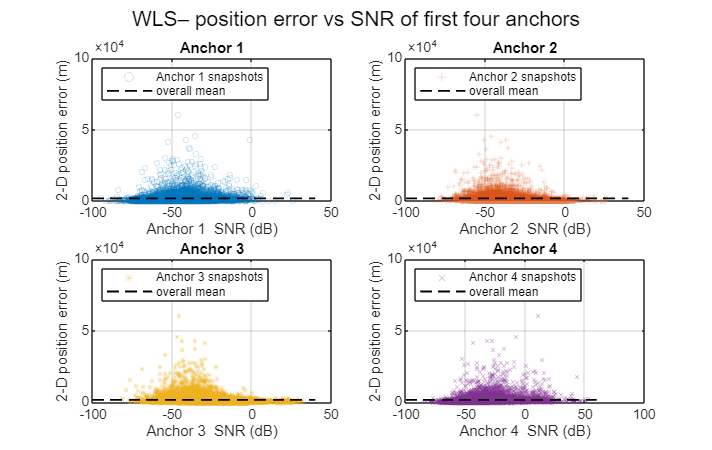


%% ---------------------------------------------------------------
%%  LS position error  vs  SNR
%% ---------------------------------------------------------------
posErr_m   = errWLS(:);              % [nPts × 1] LS position error
selAnchors = 1:4;                       % anchors to plot
win        = 200;                       % movmean window (odd integer)

figure('Position',[100 100 950 600]);
C   = lines(numel(selAnchors));         % colours for the clouds
mrk = 'o+*x';                           % four marker styles

% --- compute the two reference lines once ------------------------
errSmooth = movmean(posErr_m, win,'Endpoints','shrink'); % same everywhere
meanErr   = mean(posErr_m,'omitnan');

for a = 1:numel(selAnchors)
    snr_a = snrMatrix_dB(:, selAnchors(a));   % SNR time-series (unsorted)

    subplot(2,2,a);  hold on;
    % -------- raw scatter cloud ----------------------------------
    scatter(snr_a, posErr_m, ...
            14, mrk(a), 'MarkerEdgeColor',C(a,:), ...
            'MarkerEdgeAlpha',0.25, ...
            'DisplayName',sprintf('Anchor %d snapshots', selAnchors(a)));

    % -------- global mean (horizontal dashed line) ---------------
    plot(xlim, [meanErr meanErr], 'k--', 'LineWidth',1.2, ...
         'DisplayName','overall mean');

    % -------- cosmetics ------------------------------------------
    xlabel(sprintf('Anchor %d  SNR (dB)', selAnchors(a)));
    ylabel('2-D position error (m)'); 
    title(sprintf('Anchor %d', selAnchors(a)));
    grid on;  box on;
    legend('Location','northwest');
    ylim([0 100000]);
end

sgtitle('WLS– position error vs SNR of first four anchors');


%%%%%%%%%%%%%%%%%%%
nPts   = size(estDistMatrix_in,1);
muMLE  = zeros(nPts,2);
errMLE = zeros(nPts,1);

for i = 1:nPts
    A    = anchorPos2D;       % 2×k
    dO   = estDistMatrix_in(i, :);  % 1×k
    s    = snrMatrix_dB(i, :);      % 1×k
    init = estPosLS_i(i,:).';        % 2×1 initial LS guess

    [p, resnorm, flag] = localizeMLE_LM(A, dO, s, init);

    muMLE(i,:) = p.';
    errMLE(i)  = norm(p - truePosMatrix_in(:,i));
end

fprintf('MLE–LM per‐snapshot RMSE = %.2f m\n', sqrt(mean(errMLE.^2)));

MLE–LM per‐snapshot RMSE = 928.32 m



% Overall RLS error metrics:
MSE_MLE  = mean(errMLE.^2);
RMSE_MLE = sqrt(MSE_MLE);
MAE_MLE  = mean(RMSE_MLE);
fprintf('=== Overall MLE: MSE = %.2f m^2, RMSE = %.2f m, MAE = %.2f m ===\n', MSE_MLE, RMSE_MLE, MAE_MLE);

=== Overall MLE: MSE = 861786.23 m^2, RMSE = 928.32 m, MAE = 928.32 m ===


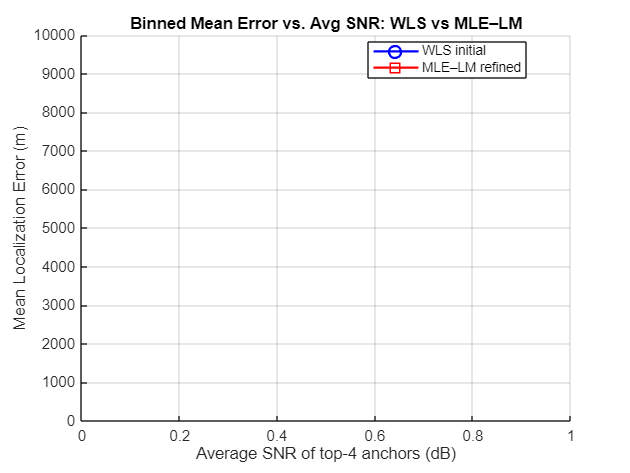


% Compute per‐snapshot average SNR over the k strongest links ---
k = 4;  
% sort each row descending:
snr_sorted = sort(snrMatrix_dB, 2, 'descend');  % nPointsIn×nBS
avgSNR = mean(snr_sorted(:,1:k), 2);            % nPointsIn×1

% Bin them by avgSNR and compute mean error in each bin ---
binEdges   = floor(min(avgSNR)) : 2 : ceil(max(avgSNR));  % 2 dB bins
binCenters = (binEdges(1:end-1) + binEdges(2:end))/2;
numBins    = numel(binCenters);

meanErrWLS = nan(1,numBins);
meanErrMLE = nan(1,numBins);
minPts     = 200;

for b = 1:numBins
    idx = avgSNR >= binEdges(b) & avgSNR < binEdges(b+1);
    if sum(idx) >= minPts
        meanErrWLS(b) = mean(errWLS(idx).^2);
        meanErrMLE(b) = mean(errMLE(idx).^2);
    end
end

% Plot both on the same figure ---
figure; hold on; grid on;
plot(binCenters, meanErrWLS, 'bo-','LineWidth',1.5,'MarkerSize',8);
plot(binCenters, meanErrMLE, 'rs-','LineWidth',1.5,'MarkerSize',8);
xlabel('Average SNR of top-4 anchors (dB)');
ylabel('Mean Localization Error (m)');
title('Binned Mean Error vs. Avg SNR: WLS vs MLE–LM');
legend('WLS initial','MLE–LM refined','Location','best');
ylim([0 10000]);

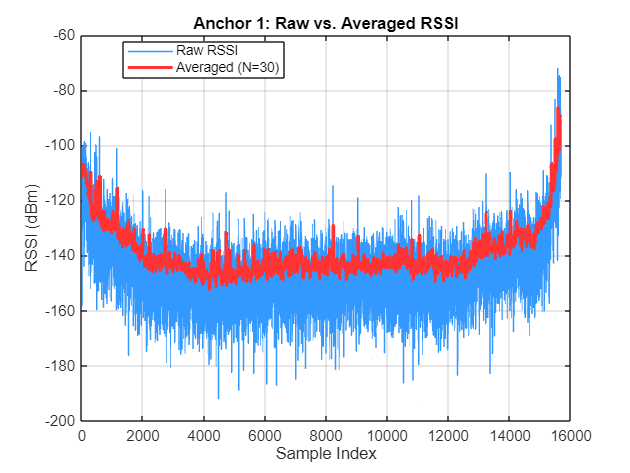


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
anchorIdx = 1;              % choose which BS to inspect
raw = rssiMatrix_in(:,anchorIdx);
avg = rssi_avg(:,anchorIdx);
n   = numel(raw);

figure('Name','Raw vs. Averaged RSSI','Color','w');
plot(1:n, raw,    '-', 'LineWidth',1, 'Color',[0.2 0.6 1], 'DisplayName','Raw RSSI');
hold on;
plot(1:n, avg,    '-', 'LineWidth',2, 'Color',[1 0.2 0.2], 'DisplayName',sprintf('Averaged (N=%d)',windowSize));
grid on;
xlabel('Sample Index');
ylabel('RSSI (dBm)');
title(sprintf('Anchor %d: Raw vs. Averaged RSSI', anchorIdx));
legend('Location','best');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% MUSIC DOA ESTIMATION PER SNAPSHOT (with realistic SNR)
anchorChosen = 1;
xA = xBS(anchorChosen);
yA = yBS(anchorChosen);

fc     = simParams.fHz;        
lambda = c / fc;
nEl    = 8;
Nsamp  = 256;                   % snapshots per trial

% Build the array & estimator once
hArray  = phased.ULA( ...
               'NumElements', nEl, ...
               'ElementSpacing', lambda/2, ...
               'Element', phased.IsotropicAntennaElement( ...
                   'FrequencyRange', [1e9 6e9]) );
hESPRIT = phased.ESPRITEstimator( ...
               'SensorArray',       hArray, ...
               'OperatingFrequency', fc);

doaArray = nan(nPointsIn,1);

for i = 1:nPointsIn
    % True DOA angle for this snapshot
    dx = truePosMatrix_in(1,i) - xA;
    dy = truePosMatrix_in(2,i) - yA;
    trueAngleDeg = rad2deg(atan2(dy,dx));

    % Compute received power from your RSSI [dBm] → [W]
    Pr_dBm = rssiMatrix_in(i);
    Pr_W   = 10^((Pr_dBm - 30)/10);   % (dBm → mW → W)

    % Generate unit-power test signal & plane wave
    txSig     = complex(randn(Nsamp,1), randn(Nsamp,1));
    rxNoNoise = collectPlaneWave(hArray, txSig, trueAngleDeg, fc);

    % Normalize plane-wave to unit power, then scale to sqrt(Pr_W)
    sigPower = mean(abs(rxNoNoise(:)).^2);
    rxNoNoise = rxNoNoise * sqrt( Pr_W / sigPower );

    % Grab your per-snapshot SNR (dB) and skip if too low
    snrThisPointdB = snrMatrix_dB(i);
    if isnan(snrThisPointdB) || snrThisPointdB < 0
        doaArray(i) = NaN;
        continue;
    end

    % Compute noise standard deviation for that SNR
    %    SNR_linear = Pr_W / noiseVar  =>  noiseVar = Pr_W / SNR_linear
    SNR_lin    = 10^( snrThisPointdB/10 );
    noiseVar   = Pr_W / SNR_lin;
    noiseSigma = sqrt(noiseVar);

    % Add complex AWGN (each branch ½·noiseVar)
    noise = (randn(size(rxNoNoise)) + 1j*randn(size(rxNoNoise))) ...
              / sqrt(2) * noiseSigma;
    rxArraySig = rxNoNoise + noise;

    % ESPRIT DOA estimate
    estAngles = step(hESPRIT, rxArraySig);
    if isempty(estAngles)
        doaArray(i) = NaN;
    else
        doaArray(i) = deg2rad(estAngles(1));
    end
end

%% Build baseline measurement noise and fuse MLE + DOA with an EKF
% ────────────────────────────────────────────────────────────────────────
fprintf('\n=== EKF fusion — start ===\n');


=== EKF fusion — start ===



nPts = size(muMLE,1);

% average SNR of k strongest anchors, per snapshot
kAnch     = 4;
snrSorted = sort(snrMatrix_dB,2,'descend');
avgSNR    = mean( snrSorted(:,1:kAnch) , 2 );        % nPts×1

% baseline (SNR = 0 dB) measurement sigmas ───────────────────────────
sigmaPos  = std(muMLE(:,1) - truePosMatrix_in(1,:)','omitnan');
sigmaAng  = std(wrapToPi(doaArray - ...
               atan2(truePosMatrix_in(2,:)'-yA, ...
                     truePosMatrix_in(1,:)'-xA)),'omitnan');

epsR      = 1e-6;                       % never allow 0 variance
varFloorPos = 1^2;                     % ≥ 1 m²
varFloorAng = deg2rad(1)^2;            % ≥ 1°²
baseR = diag([ ...
        max(sigmaPos^2 , varFloorPos) , ...
        max(sigmaPos^2 , varFloorPos) , ...
        max(sigmaAng^2 , varFloorAng)] );

% constant-velocity state model ──────────────────────────────────────
dt = 1;
F  = [1 0 dt 0 ;
      0 1 0  dt ;
      0 0 1  0 ;
      0 0 0  1 ];
Q  = diag([0 0 .1 .1]);

% pre-allocate -------------------------------------------------------
xKF   = zeros(nPts,4);                  % state: [x y vx vy]
Psave = zeros(4,4,nPts);                % covariance history

% initialise ---------------------------------------------------------
xKF(1,:)   = [muMLE(1,:) 0 0];
Psave(:,:,1) = diag([25 25 100 100]);   % vague prior

% EKF main loop ------------------------------------------------------
nPts = size(muMLE,1);
xKF(1,:)   = [muMLE(1,:) 0 0];
Psave(:,:,1) = diag([25 25 100 100]);

for k = 2:nPts
    % predict
    xPred = F * xKF(k-1,:)';
    PPred = F * Psave(:,:,k-1) * F' + Q;

    % build common quantities
    zPos = muMLE(k,:)';            % 2×1 [x̂; ŷ]
    sNR  = avgSNR(k);              % scalar dB
    scale = max(10^(-sNR/10), 1e-3);
    Rpos  = baseR(1:2,1:2) * scale; % 2×2 pos cov
    Hpos  = [1 0 0 0; 0 1 0 0];

    % position update
    yPos  = zPos - Hpos*xPred;     
    Spos  = Hpos*PPred*Hpos' + Rpos;
    Kpos  = PPred*Hpos'/Spos;
    xUp   = xPred + Kpos*yPos;
    PUp   = (eye(4)-Kpos*Hpos)*PPred;

    % DOA update (only if valid)
    zBear = doaArray(k);
    if ~isnan(zBear)
        dx = xUp(1)-xA;  dy = xUp(2)-yA;
        r2 = max(dx*dx+dy*dy,1);
        Hb = [-dy/r2  dx/r2  0 0];    % 1×4
        z_h = atan2(dy,dx);
        yb  = wrapToPi(zBear - z_h);

        Rb   = baseR(3,3) * scale;   % scalar
        Sb   = Hb*PUp*Hb' + Rb;      
        Kb   = (PUp*Hb')/Sb;         
        xUp  = xUp + Kb*yb;
        PUp  = (eye(4)-Kb*Hb)*PUp;
    end

    % save
    xKF(k,:)     = xUp';
    Psave(:,:,k) = PUp;

    % debug-print for first 10
    if k<=10
      err = norm(xUp(1:2) - truePosMatrix_in(:,k));
      fprintf('k=%2d | SNR=%5.1f dB | DOA-ok=%d | pre=[%7.1f,%7.1f] | upd=[%7.1f,%7.1f] | err=%6.1f\n',...
              k, sNR, ~isnan(zBear), ...
              xPred(1),xPred(2), xUp(1),xUp(2), err);
    end
end

k= 2 | SNR= -5.8 dB | DOA-ok=0 | pre=[ 2747.1,  133.6] | upd=[ 2747.0,  133.6] | err=1321.3
k= 3 | SNR= -9.1 dB | DOA-ok=0 | pre=[ 2747.0,  133.5] | upd=[ 2746.9,  133.5] | err=1321.3
k= 4 | SNR= -6.3 dB | DOA-ok=0 | pre=[ 2746.8,  133.5] | upd=[ 2746.3,  133.1] | err=1320.7
k= 5 | SNR=-11.8 dB | DOA-ok=0 | pre=[ 2746.1,  132.9] | upd=[ 2746.0,  132.7] | err=1320.4
k= 6 | SNR=-13.0 dB | DOA-ok=0 | pre=[ 2745.7,  132.5] | upd=[ 2745.6,  132.4] | err=1320.1
k= 7 | SNR= -9.6 dB | DOA-ok=0 | pre=[ 2745.3,  132.2] | upd=[ 2744.4,  131.3] | err=1318.7
k= 8 | SNR= -5.2 dB | DOA-ok=0 | pre=[ 2743.9,  130.9] | upd=[ 2739.9,  128.3] | err=1313.7
k= 9 | SNR= -7.7 dB | DOA-ok=0 | pre=[ 2738.9,  127.5] | upd=[ 2736.4,  126.8] | err=1309.9
k=10 | SNR=-11.3 dB | DOA-ok=0 | pre=[ 2735.1,  126.0] | upd=[ 2733.5,  124.2] | err=1306.3



fprintf('EKF fusion complete: %d steps processed.\n', nPts);

EKF fusion complete: 15689 steps processed.



%% Plots: KF vs MLE vs WLS – error vs SNR
% ────────────────────────────────────────────────────────────────────────
trueX  = truePosMatrix_in(1,:)';
trueY  = truePosMatrix_in(2,:)';

errWLS = errWLS(:);                      % from §7
errMLE = errMLE(:);                     % from §8
errKF  = hypot(xKF(:,1)-trueX, xKF(:,2)-trueY);

% Overall KF error metrics:
MSE_KF  = mean(errKF.^2);
RMSE_KF = sqrt(MSE_KF);
MAE_KF  = mean(errKF);

fprintf('=== Overall KF: MSE = %.2f m^2, RMSE = %.2f m, MAE = %.2f m ===\n', ...
        MSE_KF, RMSE_KF, MAE_KF);

=== Overall KF: MSE = 208228.62 m^2, RMSE = 456.32 m, MAE = 326.87 m ===



% print first 10 snapshots
Nprint = min(10, nPts);
fprintf('\nFirst %d snapshots (SNR | WLS | MLE | KF):\n', Nprint);


First 10 snapshots (SNR | WLS | MLE | KF):


for i = 1:Nprint
    fprintf(' %5.1f dB  | %6.2f | %6.2f | %6.2f\n',...
        avgSNR(i), errWLS(i), errMLE(i), errKF(i));
end

 -14.4 dB  | 5623.89 | 1321.32 | 1321.32
  -5.8 dB  | 1000.44 | 784.24 | 1321.34
  -9.1 dB  | 1610.54 | 456.82 | 1321.28
  -6.3 dB  | 1086.05 | 414.79 | 1320.67
 -11.8 dB  | 1816.34 | 820.42 | 1320.37
 -13.0 dB  | 7599.68 | 950.00 | 1320.09
  -9.6 dB  | 752.54 | 436.00 | 1318.71
  -5.2 dB  | 1071.57 | 251.21 | 1313.68
  -7.7 dB  | 644.89 | 410.53 | 1309.94
 -11.3 dB  | 622.78 | 672.07 | 1306.27


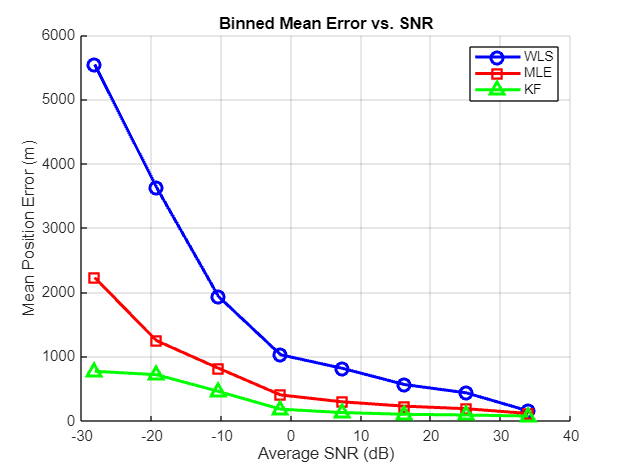


% bin into 8 equal-width SNR bins
nBins    = 8;
binEdges = linspace(min(avgSNR), max(avgSNR), nBins+1);
binCenters = (binEdges(1:end-1) + binEdges(2:end))/2;

meanErr = nan(nBins,3);
for b = 1:nBins
    idx = avgSNR >= binEdges(b) & avgSNR < binEdges(b+1);
    if any(idx)
        meanErr(b,1) = mean(errWLS(idx));
        meanErr(b,2) = mean(errMLE(idx));
        meanErr(b,3) = mean(errKF(idx));
    end
end

% binned-mean plot
figure('Color','w'); hold on; grid on;
plot(binCenters, meanErr(:,1), 'bo-','LineWidth',2,'MarkerSize',8);
plot(binCenters, meanErr(:,2), 'rs-','LineWidth',2,'MarkerSize',8);
plot(binCenters, meanErr(:,3), 'g^-','LineWidth',2,'MarkerSize',8);
xlabel('Average SNR (dB)');
ylabel('Mean Position Error (m)');
title('Binned Mean Error vs. SNR');
legend('WLS','MLE','KF','Location','northeast');

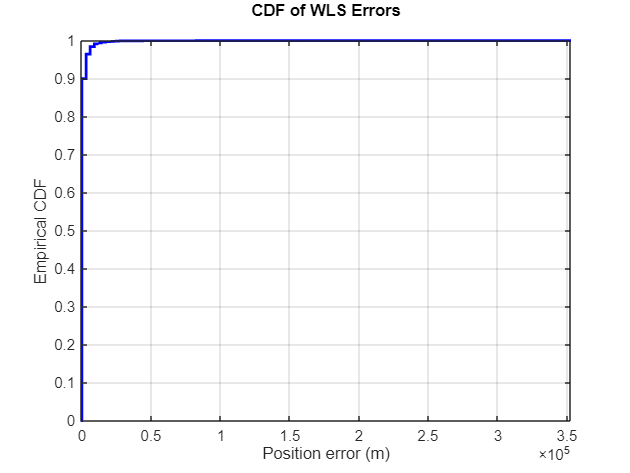


%%%%%%%%%%%%%%===CDF===%%%%%%%%%%%%%%%%%
plot_hist_cdf(errWLS, 'b', 'WLS');

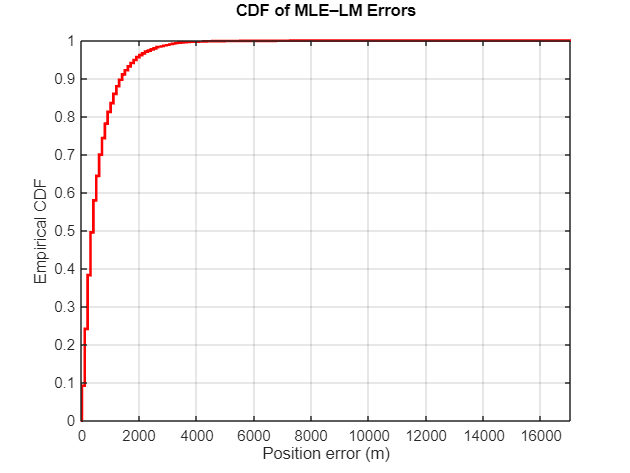

plot_hist_cdf(errMLE, 'r', 'MLE–LM');

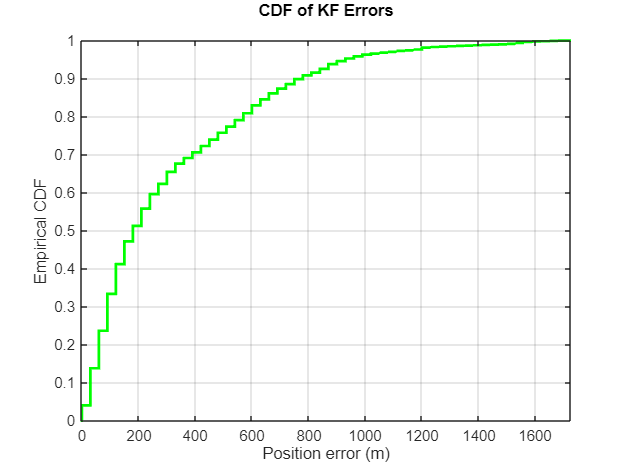

plot_hist_cdf(errKF,  'g', 'KF');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%CRLB%%%%%%%%%%%%%%%%
kAnch      = 4;                     % same k used in WLS/MLE
CRLB_trace = nan(nPts,1);

for i = 1:nPts
    % 1) select the k strongest anchors
    [~, idx] = sort(snrMatrix_dB(i,:), 'descend');
    sel      = idx(1:kAnch);
    A        = anchorPos2D(:,sel);         % 2×k
    d_i      = estDistMatrix_in(i,sel);    % 1×k
    beta     = betaMatrix_in(i,sel);       % 1×k
    los      = losMatrix_in(i,sel);        % 1×k

    % 2) per-link range noise σ_d
    sigma_rssi = getShadowSigma('uma',true).*los + ...
                 getShadowSigma('uma',false).*(~los);
    sigma_d    = (log(10)./(10*beta)) .* d_i .* sigma_rssi;  % 1×k

    % 3) build range FIM
    Jr = zeros(kAnch,2);
    for j = 1:kAnch
        dx        = xKF(i,1) - A(1,j);
        dy        = xKF(i,2) - A(2,j);
        dist      = sqrt(dx^2 + dy^2);
        Jr(j,:)   = [dx/dist, dy/dist];
    end
    FIM_r = Jr' * diag(1./(sigma_d.^2)) * Jr;  % 2×2

    % 4) build DOA FIM (if available)
    if ~isnan(doaArray(i))
        dx    = xKF(i,1) - xA;
        dy    = xKF(i,2) - yA;
        r2    = dx^2 + dy^2;
        Jb    = (1/r2) * [-dy, dx];             % 1×2
        sigma_b = sqrt(baseR(3,3) * max(10^(-avgSNR(i)/10),1e-3));
        FIM_b  = Jb' * (1/sigma_b^2) * Jb;      % 2×2
    else
        FIM_b = zeros(2);
    end

    % 5) total FIM & robust inversion
    FIM_tot = FIM_r + FIM_b + eye(2)*1e-6;     % tiny regularizer
    epsF    = 1e-6;
    [~, p]  = chol(FIM_tot);
    if p>0
        % first bump
        FIM_tot = FIM_tot + eye(2)*epsF;
        [~, p]  = chol(FIM_tot);
        if p>0
            % second bump
            FIM_tot = FIM_tot + eye(2)*(10*epsF);
            [~, p]  = chol(FIM_tot);
        end
    end

    if p==0
        CRLB_mat = inv(FIM_tot);
    else
        warning('CRLB: singular FIM at idx=%d, using pinv.', i);
        CRLB_mat = pinv(FIM_tot);
    end

    CRLB_trace(i) = trace(CRLB_mat);
end

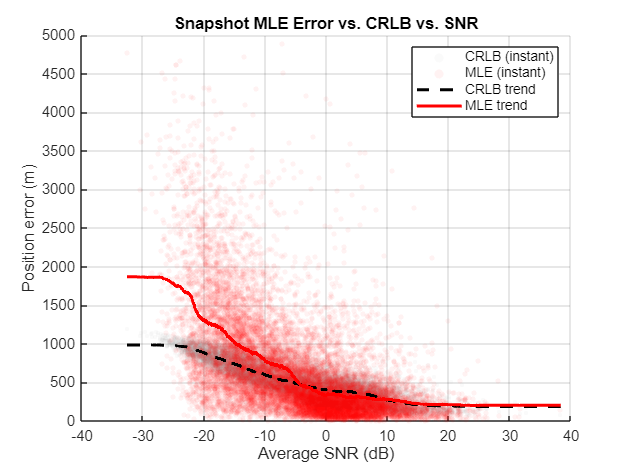


% 6) Plot CRLB RMSE vs SNR
crlbRMSE = sqrt(CRLB_trace);   % sqrt(var_x + var_y)
nBins    = 8;
edges    = linspace(min(avgSNR), max(avgSNR), nBins+1);
meanCRLB = nan(nBins,1);
for b = 1:nBins
    idx         = avgSNR>=edges(b) & avgSNR<edges(b+1);
    meanCRLB(b) = mean(crlbRMSE(idx));
end

% 1) sort SNR for smooth trend lines
[snr_s, order] = sort(avgSNR);
mle_s          = errMLE(order);
crlb_s         = crlbRMSE(order);

% 2) choose smoothing window (5% of data)
win = max(floor(0.05 * nPts), 5);

% 3) compute continuous trends
trend_MLE  = movmean(mle_s,  win);
trend_CRLB = movmean(crlb_s, win);

% 4) figure
figure('Color','w'); hold on; grid on;

% grey CRLB instantaneous cloud
scatter(avgSNR, crlbRMSE, 8, [0.6 0.6 0.6], ...
        'filled','MarkerFaceAlpha',.05);

% red MLE instantaneous cloud
scatter(avgSNR, errMLE, 12, 'r', ...
        'filled','MarkerFaceAlpha',.05);

% dashed black CRLB trend
plot(snr_s, trend_CRLB, 'k--', 'LineWidth',2);

% solid red MLE trend
plot(snr_s, trend_MLE, 'r-', 'LineWidth',2);

xlabel('Average SNR (dB)');
ylabel('Position error (m)');
title('Snapshot MLE Error vs. CRLB vs. SNR');
legend('CRLB (instant)','MLE (instant)','CRLB trend','MLE trend',...
       'Location','northeast');
ylim([0, 5000]);


% 5) bin‐based gap analysis
nBins   = 8;
edges   = linspace(min(avgSNR), max(avgSNR), nBins+1);
centers = (edges(1:end-1)+edges(2:end))/2;

meanCRLB = nan(nBins,1);
meanMLE  = nan(nBins,1);
for b = 1:nBins
    idx         = avgSNR>=edges(b) & avgSNR<edges(b+1);
    meanCRLB(b) = mean(crlbRMSE(idx));
    meanMLE(b)  = mean(errMLE(idx));
end

absGap = meanMLE - meanCRLB;           % absolute difference [m]
relGap = absGap ./ meanCRLB * 100;     % percent above CRLB

fprintf('\nSNR bin   |  CRLB   |   MLE   |  Δ (m)  |  Δ (%%)\n');


SNR bin   |  CRLB   |   MLE   |  Δ (m)  |  Δ (%)


fprintf('----------+---------+---------+---------+---------\n');

----------+---------+---------+---------+---------


for b = 1:nBins
    fprintf('%6.1f dB  | %7.1f | %7.1f | %7.1f |   %5.1f%%\n',...
        centers(b), meanCRLB(b), meanMLE(b), absGap(b), relGap(b));
end

 -28.2 dB  |  1026.9 |  2225.5 |  1198.7 |   116.7%
 -19.3 dB  |   832.8 |  1245.5 |   412.7 |    49.6%
 -10.4 dB  |   609.8 |   816.2 |   206.3 |    33.8%
  -1.5 dB  |     NaN |   401.7 |     NaN |     NaN%
   7.3 dB  |     NaN |   293.9 |     NaN |     NaN%
  16.2 dB  |   211.5 |   227.2 |    15.8 |     7.5%
  25.1 dB  |   165.1 |   186.7 |    21.7 |    13.1%
  34.0 dB  |   162.1 |   113.0 |   -49.1 |   -30.3%



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%% ------------------------------------------------------------------------
function [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
% LOCALXY2LATLON Convert local XY coordinates (meters) back to latitude/longitude (degrees).
%
%   [lat, lon] = localXY2LatLon(x, y, latRef, lonRef)
%
%   This function uses a simple equirectangular approximation valid
%   for relatively small distances from the reference point.
%
%   Inputs:
%       x      - local East coordinate in meters (can be scalar or vector)
%       y      - local North coordinate in meters (can be scalar or vector)
%       latRef - reference latitude in degrees (scalar)
%       lonRef - reference longitude in degrees (scalar)
%
%   Outputs:
%       lat - latitude in degrees (same size as x,y)
%       lon - longitude in degrees (same size as x,y)
%
%   Example:
%       % Suppose we have local coords x=3000m East, y=1000m North of (latRef=50, lonRef=8)
%       % Convert them back to lat/lon:
%       [lat, lon] = localXY2LatLon(3000, 1000, 50, 8);

    % Convert reference latitude to radians
    lat0 = deg2rad(latRef);

    % Approximate meters per degree of latitude/longitude
    mPerDegLat = 111320;           % ~111.32 km/deg
    mPerDegLon = 111320 * cos(lat0);

    % Convert back to lat/lon in degrees
    lat = latRef + (y ./ mPerDegLat);
    lon = lonRef + (x ./ mPerDegLon);
end

function [x, y] = latLon2localXY(lat, lon, latRef, lonRef)
    % Convert lat/lon to local XY in meters (equirectangular approximation)
    R = 6371000; % Earth radius in meters
    lat0 = deg2rad(latRef);

    mPerDegLat = 111320;           % approx. meters per degree latitude
    mPerDegLon = 111320 * cos(lat0); % meters/deg at latRef

    x = (lon - lonRef) .* mPerDegLon;  % Easting
    y = (lat - latRef) .* mPerDegLat;  % Northing
end

%% --- RSSI Calculation - 3GPP Model ---
function [rssi, pathLoss_dB, isLOS, beta] = calculateRSSI_3GPP(anchorPos, tgtPos, simParams, scenario)
% calculateRSSI_3GPP Computes the received signal strength (RSSI) for a given base station and target.
%   This function calculates the RSSI by taking into account path loss, shadowing,
%   and small-scale fading (using either Rician or Rayleigh fading) based on 3GPP models.
%
%   Inputs:
%     anchorPos : [1x2] Base station coordinates
%     tgtPos    : [1x2] Target/user coordinates
%     simParams : Structure containing simulation parameters (e.g., txPower, txGain, rxGain, etc.)
%     scenario  : A string specifying the environment ('uma', 'rma', or 'inh')
%
%   Outputs:
%     rssi        : Final calculated RSSI in dBm
%     pathLoss_dB : Combined path loss in dB (including shadowing, before applying fading)

    
    % -- Compute 2D and 3D Distances --

    d2D = sqrt((tgtPos(1) - anchorPos(1))^2 + (tgtPos(2) - anchorPos(2))^2);
    d3D = sqrt(d2D^2 + (simParams.hBS - simParams.hUT)^2);
    
    % -- Determine LOS/NLOS --
    P_LOS = calculate_LOS_probability(d2D, scenario, simParams.hUT);
    isLOS = (rand() < P_LOS);

    beta = getPathLossExponent(scenario, isLOS);
    
    % -- Calculate Path Loss Depending on LOS/NLOS --
    if isLOS
        PL = getLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        shadowSigma = getShadowSigma(scenario, true);
    else
        [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, simParams.d_bp, simParams.fHz/1e9, simParams.hBS, simParams.hUT, simParams.h);
        PL = max(PL_LOS, PL_NLOS);
        shadowSigma = getShadowSigma(scenario, false);
    end
    
    if simParams.useShadowing   
        shadowing = normrnd(0,shadowSigma);
    else
        shadowing = 0;
    end
    pathLoss_dB = PL + shadowing;
    
        
    %small-scale fading:
    % Rician fading if LOS
    if simParams.useFading
        if isLOS          % Rician
            K = 10;
            h_los  = sqrt(K/(K+1));
            h_nlos = sqrt(1/(2*(K+1)))*(randn() + 1j*randn());
            h_fad  = h_los + h_nlos;
        else              % Rayleigh
            h_fad  = (randn() + 1j*randn())/sqrt(2);
        end
        fadingPower_dB = 10*log10(abs(h_fad)^2);
    else
        fadingPower_dB = 0;
    end
    
    % RSSI calculation
    rssi = simParams.txPower + simParams.txGain + simParams.rxGain - pathLoss_dB - simParams.systemLoss + fadingPower_dB;
end


%% --- LOS Probability Calculation ---
function P_LOS = calculate_LOS_probability(d2D, scenario, hUT)
% calculate_LOS_probability Returns the probability of a LOS link based on 3GPP TR 38.901.
%
%   Inputs:
%     d2D      : 2D distance between transmitter and receiver (meters)
%     scenario : Scenario type ('uma', 'rma', 'inh')
%     hUT      : User terminal height (meters)
%
%   Output:
%     P_LOS : Probability of a LOS connection

    switch lower(scenario)
        case 'uma'
            if d2D <= 18
                P_LOS = 1;
            else
                C_hUT = 0;
                if (13 < hUT) && (hUT <= 23)
                    C_hUT = ((hUT - 13)/10)^1.5;
                end
                P_LOS = (18/d2D + exp(-d2D/63) * (1 - 18/d2D)) * (1 + C_hUT * (5/4) * (d2D/100)^3 * exp(-d2D/150));
            end
        case 'rma'
            if d2D <= 10
                P_LOS = 1;
            else
                P_LOS = exp(-((d2D - 10)/1000));
            end
        case 'inh'
            if d2D <= 1.2
                P_LOS = 1;
            else
                P_LOS = exp(-(d2D - 1.2)/4.7);
                P_LOS = max(min(P_LOS, 1), 0);
            end
        otherwise
            P_LOS = 0.5;
    end
end

%% --- LOS Path Loss Model ---
function PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
%   Inputs:
%     scenario : Environment type ('uma', 'rma', or 'inh')
%     d2D      : 2D distance (m)
%     d3D      : 3D distance (m)
%     d_bp     : Breakpoint distance (m)
%     fGHz     : Carrier frequency (GHz)
%     hBS      : Base station height (m)
%     hUT      : User terminal height (m)
%     h        : Average building height for RMa(m)
%
%   Output:
%     PL_LOS : LOS path loss in dB
    switch lower(scenario)
        case 'uma'
            if d2D <= d_bp
                PL_LOS = 28 + 22*log10(d3D) + 20*log10(fGHz);
            else
                PL_LOS = 28 + 40*log10(d3D) + 20*log10(fGHz) - 9*log10(d_bp^2 + (hBS-hUT)^2);
            end
        case 'rma'
            if d2D <= d_bp
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D;
            else
                PL_LOS = 20*log10(40*pi*d2D*fGHz/3) + min(0.03*h^(1.72),10)*log10(d3D) - min(0.044*h^(1.72),14.77) + 0.002*log10(h)*d3D + 40*log10(d3D/d_bp);
            end
        case 'inh'
            PL_LOS = 32.4 + 17.3*log10(d3D) + 20*log10(fGHz);
        otherwise
            PL_LOS = 0;
    end
end

%% --- NLOS Path Loss Model ---
function [PL_LOS, PL_NLOS] = getNLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h)
% getNLOSpathLoss Computes the non-line-of-sight (NLOS) path loss as per 3GPP TR 38.901.
%
%   This function returns both the LOS and NLOS estimates, and the final
%   loss is taken as the maximum of the two.
%
%   Inputs:
%     scenario : Environment type ('uma', 'rma', or 'inh')
%     d2D      : 2D distance (m)
%     d3D      : 3D distance (m)
%     d_bp     : Breakpoint distance (m)
%     fGHz     : Carrier frequency (GHz)
%     hBS      : Base station height (m)
%     hUT      : User terminal height (m)
%     h        : Average building height for RMa(m)
%
%   Outputs:
%     PL_LOS  : LOS path loss (for reference)
%     PL_NLOS : NLOS path loss in dB

    PL_LOS = getLOSpathLoss(scenario, d2D, d3D, d_bp, fGHz, hBS, hUT, h);
    switch lower(scenario)
        case 'uma'
            PL_prime = 13.54 + 39.08*log10(d3D) + 20*log10(fGHz) - 0.6*(hUT - 1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'rma'
            W = 20; % Average street width (m)
            PL_prime = 161.04 - 7.1*log10(W) + 7.5*log10(hBS) - (24.37 - 3.7*(hBS/hUT)^2)*log10(hUT) + (43.42 - 3.1*log10(hUT))*(log10(d3D)-3) + 20*log10(fGHz) - 0.6*(hUT-1.5);
            PL_NLOS = max(PL_LOS, PL_prime);
        case 'inh'
            PL_prime1 = 38.3*log10(d3D) + 17.3 + 24.9*log10(fGHz);
            PL_prime2 = 32.4 + 20*log10(fGHz) + 31.9*log10(d3D);
            PL_NLOS = max([PL_LOS, PL_prime1, PL_prime2]);
        otherwise
            PL_NLOS = PL_LOS;
    end
end

function beta = getPathLossExponent(scenario, isLOS)
    switch lower(scenario)
        case 'uma', beta = isLOS*2.2 + (~isLOS)*3.5;
        case 'rma', beta = isLOS*2.0 + (~isLOS)*2.75;
        case 'inh', beta = isLOS*1.8 + (~isLOS)*3.0;
        otherwise,  beta = 3.0;
    end
end

%% --- Shadowing Sigma---
function sigmaVal = getShadowSigma(scenario, isLOS)
% getShadowSigma Returns the standard deviation (in dB) used for log-normal shadowing.

%   Inputs:
%     scenario : Environment type ('uma', 'rma', 'inh')
%     isLOS    : Boolean flag (true for LOS, false for NLOS)
%
%   Output:
%     sigmaVal : Standard deviation in dB

    switch lower(scenario)
        case 'uma'
            sigmaVal = isLOS * 4 + (~isLOS) * 6;
        case 'rma'
            sigmaVal = isLOS * 4 + (~isLOS) * 8;
        case 'inh'
            sigmaVal = isLOS * 3 + (~isLOS) * 8;
        otherwise
            sigmaVal = 5;
    end
end

function d2D_m = rssi2distance_3gpp(rssi_dBm, isLOS, p)
%   Inputs:
%     rssi_dBm : M×N array of RSSI [dBm]
%     isLOS    : M×N logical/NaN array
%                  true  = force LOS
%                  false = force NLOS
%                  NaN   = unknown → pick best
%     p        : struct with fields
%                  txPower, txGain, rxGain, systemLoss,
%                  fHz, hBS, hUT, d_bp
%
%   Output:
%     d2D_m    : M×N array of horizontal distances [m]

  % Preallocate output
  d2D_m = zeros(size(rssi_dBm));

  % 1) observed path loss [dB]
  PL = p.txPower + p.txGain + p.rxGain - p.systemLoss - rssi_dBm;

  % 2) constants
  f   = p.fHz/1e9;            % in GHz
  dh  = p.hBS - p.hUT;         % height difference
  db  = p.d_bp;                % breakpoint

  C1 = 28 + 20*log10(f);                             % LOS, d2D ≤ db
  C2 = 28 + 20*log10(f) - 9*log10(db^2 + dh^2);      % LOS, d2D > db
  C3 = 13.54 + 20*log10(f) - 0.6*(p.hUT - 1.5);       % NLOS

  % 3) invert each branch
  d3_L1 = 10.^((PL - C1)/22);
  d2_L1 = sqrt(max(d3_L1.^2 - dh^2, 0));

  d3_L2 = 10.^((PL - C2)/40);
  d2_L2 = sqrt(max(d3_L2.^2 - dh^2, 0));

  d3_NL = 10.^((PL - C3)/39.08);
  d2_NL = sqrt(max(d3_NL.^2 - dh^2, 0));

  % 4) assign forced-LOS
  maskLOS  = (isLOS == 1);
  maskL1   = maskLOS & (d2_L1 <= db);
  maskL2   = maskLOS & (d2_L1 >  db);
  d2D_m(maskL1) = d2_L1(maskL1);
  d2D_m(maskL2) = d2_L2(maskL2);

  % 5) assign forced-NLOS
  maskNLOS = (isLOS == 0);
  d2D_m(maskNLOS) = d2_NL(maskNLOS);

  % 6) resolve unknown by best‐fit to observed PL
  maskU = isnan(isLOS);
  if any(maskU(:))
    % recompute forward PL for each branch
    PL1 = 28 + 22*log10(d3_L1) + 20*log10(f);
    PL2 = 28 + 40*log10(d3_L2) + 20*log10(f) - 9*log10(db^2 + dh^2);
    PL3 = C3 + 39.08*log10(d3_NL);

    % compute absolute errors
    e1 = abs(PL1 - PL);
    e2 = abs(PL2 - PL);
    e3 = abs(PL3 - PL);

    % find minimal error branch per element
    [~,which] = min(cat(3,e1,e2,e3), [], 3);

    % assign distances accordingly
    d2D_m(maskU & which==1) = d2_L1(maskU & which==1);
    d2D_m(maskU & which==2) = d2_L2(maskU & which==2);
    d2D_m(maskU & which==3) = d2_NL(maskU & which==3);
  end
end

function [estPosWLS, rmseWLS, errsWLS] = estimatePositionWLS(anchorPos2D, estDistMatrix, snrMatrix_dB, k, truePosMatrix)
%   This function estimates 2D positions by solving a weighted
%   least-squares problem for each snapshot, using SNR-based weights.
%
%   Inputs:
%     anchorPos2D    : 2×nBS matrix of anchor coordinates [x; y]
%     estDistMatrix  : nPts×nBS matrix of estimated ranges (meters)
%     snrMatrix_dB   : nPts×nBS matrix of link SNRs (dB)
%     k              : number of anchors to select by highest SNR (scalar)
%                      If empty or omitted, all anchors are used.
%     truePosMatrix  : (optional) nPts×2 true positions for error calculation
%
%   Outputs:
%     estPosWLS      : nPts×2 estimated positions [x, y]
%     rmseWLS        : scalar RMSE over all snapshots (empty if no truePosMatrix)
%     errsWLS        : nPts×1 Euclidean errors (empty if no truePosMatrix)

    [nPts, nBS] = size(estDistMatrix);
    estPosWLS    = zeros(nPts,2);
    errsWLS      = [];
    rmseWLS      = [];

    for i = 1:nPts
        d_i   = estDistMatrix(i, :);
        snr_i = snrMatrix_dB(i, :);

        % Select top-k anchors by SNR, if requested
        if exist('k','var') && ~isempty(k) && k < nBS
            [~, idxSort] = sort(snr_i, 'descend');
            selIdx = idxSort(1:k);
        else
            selIdx = 1:nBS;
        end

        % Weights: linear-scale SNR
        w = 10.^( snr_i(selIdx) / 10 );
        w = w / sum(w);            % normalize

        % Reference anchor (first in selIdx)
        xBS = anchorPos2D(1, selIdx);
        yBS = anchorPos2D(2, selIdx);
        d_sel = d_i(selIdx);

        % Build linearized system (k-1 equations)
        kSel = numel(selIdx);
        A = zeros(kSel-1,2);
        b = zeros(kSel-1,1);
        x1 = xBS(1);  y1 = yBS(1);  d1 = d_sel(1);
        for j = 2:kSel
            xi = xBS(j);  yi = yBS(j);  di = d_sel(j);
            A(j-1,:) = [2*(xi - x1), 2*(yi - y1)];
            b(j-1)   = (xi^2 - x1^2) + (yi^2 - y1^2) - (di^2 - d1^2);
        end

        % Apply weights to each equation (use weight of anchor j)
        w_eq = w(2:end);
        W    = diag(w_eq);

        % Solve weighted normal equations: (A' W A) p = A' W b
        p = (A' * W * A) \ (A' * W * b);
        estPosWLS(i,:) = p';
    end

    % Error metrics if true positions provided
    if exist('truePosMatrix','var') && ~isempty(truePosMatrix)
        errsWLS = sqrt(sum((estPosWLS - truePosMatrix).^2, 2));
        rmseWLS = sqrt(mean(errsWLS.^2));
    end
end

function [pMLE, resnorm, exitflag, nIter] = localizeMLE_LM(anchorPos2D, dObs, snr_dB, initGuess, varargin)
% INPUTS:
%   anchorPos2D : 2×k matrix of anchor positions [x;y]
%   dObs        : 1×k vector of measured ranges
%   snr_dB      : 1×k vector of SNRs in dB (1 m σ₀ at 0 dB)
%   initGuess   : 2×1 initial [x; y] guess
%
% OPTIONAL NAME–VALUE PAIRS:
%   'MaxIter'   : maximum iterations    (default 30)
%   'TolFun'    : ‖Δcost‖ tolerance     (1e-6)
%   'TolStep'   : ‖Δp‖ tolerance        (1e-6)
%   'Lambda0'   : initial LM damping    (1e-3)
%
% OUTPUTS:
%   pMLE    : 2×1 estimated position
%   resnorm : Σ rᵢ(pMLE)²  (weighted)
%   exitflag:  1 → converged, 0 → max iterations hit
%   nIter   : iterations actually executed
%
%
% -------------------------------------------------------------------------

% ---------- user-tunable defaults ---------------------------------------
opts.MaxIter  = 30;
opts.TolFun   = 1e-6;
opts.TolStep  = 1e-6;
opts.Lambda0  = 1e-3;

% ---------- override with name-value pairs ------------------------------
if ~isempty(varargin)
    opts = parseNameValue(opts, varargin{:});
end

% ---------- pre-compute per-link σ from SNR -----------------------------
sigma0 = 1;                                    % 1 m @ 0 dB
sigma  = sigma0 ./ sqrt(10.^(snr_dB/10));      % 1×k row

% ---------- initialise --------------------------------------------------
p       = initGuess(:);                        % ensure a column
lambda  = opts.Lambda0;
exitflag = 0;

% normalized ranges and Jacobian anon helper functions
residual = @(p) (dObs - vecnorm(p - anchorPos2D)) ./ sigma;
Jfun     = @(p) -( (p - anchorPos2D) ./ vecnorm(p - anchorPos2D) )./ sigma;                                  % 2×k

% ---------- initial cost ------------------------------------------------
r        = residual(p).';                      % k×1 column
cost     = 0.5 * (r.'*r);

% ---------- LM main loop -----------------------------------------------
for nIter = 1:opts.MaxIter

    % Jacobian (k×2) and normal-equation blocks
    J   = Jfun(p).';                           % k×2
    H   = J.'*J;                               % 2×2 approximate Hessian
    g   = J.'*r;                               % 2×1 gradient

    % Stopping on gradient
    if norm(g, inf) < 1e-12
        exitflag = 1;  break
    end

    % Solve the damped normal equations: (H + λI) Δ = -g
    delta = -(H + lambda*eye(2)) \ g;          % 2×1 step

    % Test for very small step
    if norm(delta) <= opts.TolStep*(norm(p)+opts.TolStep)
        exitflag = 1;  break
    end

    % Trial point and its cost
    pTrial = p + delta;
    rTrial = residual(pTrial).';
    costTrial = 0.5 * (rTrial.'*rTrial);

    rho = (cost - costTrial) / (0.5*delta.'*(lambda*delta - g));

    if rho > 0            % --- SUCCESS: accept the step -------------
        p      = pTrial;
        r      = rTrial;
        cost   = costTrial;

        % Check function tolerance
        if 2*abs(costTrial - cost) <= opts.TolFun*(costTrial+cost+eps)
            exitflag = 1;  break
        end

        % decrease λ (Gauss-Newton likeness grows)
        lambda = lambda * max(1/3, 1 - (2*rho-1)^3);
        lambda = max(lambda, 1e-16);
    else                   % --- FAILURE: reject, increase λ ----------
        lambda = lambda * 2;
    end
end

% ------------ outputs ---------------------------------------------------
pMLE    = p;
resnorm = sum(r.^2);

if nIter >= opts.MaxIter && exitflag~=1
    exitflag = 0;
end
end

% ========================================================================
%  Small utility for name–value pairs
% ------------------------------------------------------------------------
function S = parseNameValue(S, varargin)
    if mod(numel(varargin),2)~=0
        error('Name–value pairs must come in even number.');
    end
    for k = 1:2:numel(varargin)
        name = varargin{k};
        if isfield(S, name)
            S.(name) = varargin{k+1};
        else
            error('Unknown option "%s".', name);
        end
    end
end

function plot_hist_cdf(errVec, color, methodName)
    lim = prctile(errVec, 100);
    figure('Color','w');
    histogram(errVec(errVec<=lim), ...
              'BinMethod','fd', ...          % Freedman–Diaconis rule
              'Normalization','cdf', ...
              'DisplayStyle','stairs', ...
              'LineWidth',1.8, ...
              'EdgeColor',color);
    grid on;
    xlabel('Position error (m)');
    ylabel('Empirical CDF');
    title(sprintf('CDF of %s Errors\n', ...
                  methodName));
    xlim([0 lim]);
    ylim([0 1]);
end

%% ------------------------------------------------------------------------